## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv2 Intro

In this scrip, we try to adjust para automatically. We try the **function fitness**.

Now lsqcurvefit function have no ability to fit.

## Import data and previewing

The data come from expomential fitness data.

experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;%p47_5s
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);



## Function Fitness

%exp_fit_fun=@(p, t) p(1)*exp(p(2)*t)+p(3)*exp(p(4)*t);
PDE_MSD_func = @(p, t) FDE_get_MSD(p(1),p(2),p(3),t);
%init para
para0=[6e-7,0.5,1e-14];

p0 = 	1.0e+05 *

    1.0460    0.0000   -0.7307   -0.0000


p = lsqcurvefit(PDE_MSD_func, para0, t, interceptive_experiment_MSD);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


p =    -0.0000   -0.0942    0.0000   -0.0670


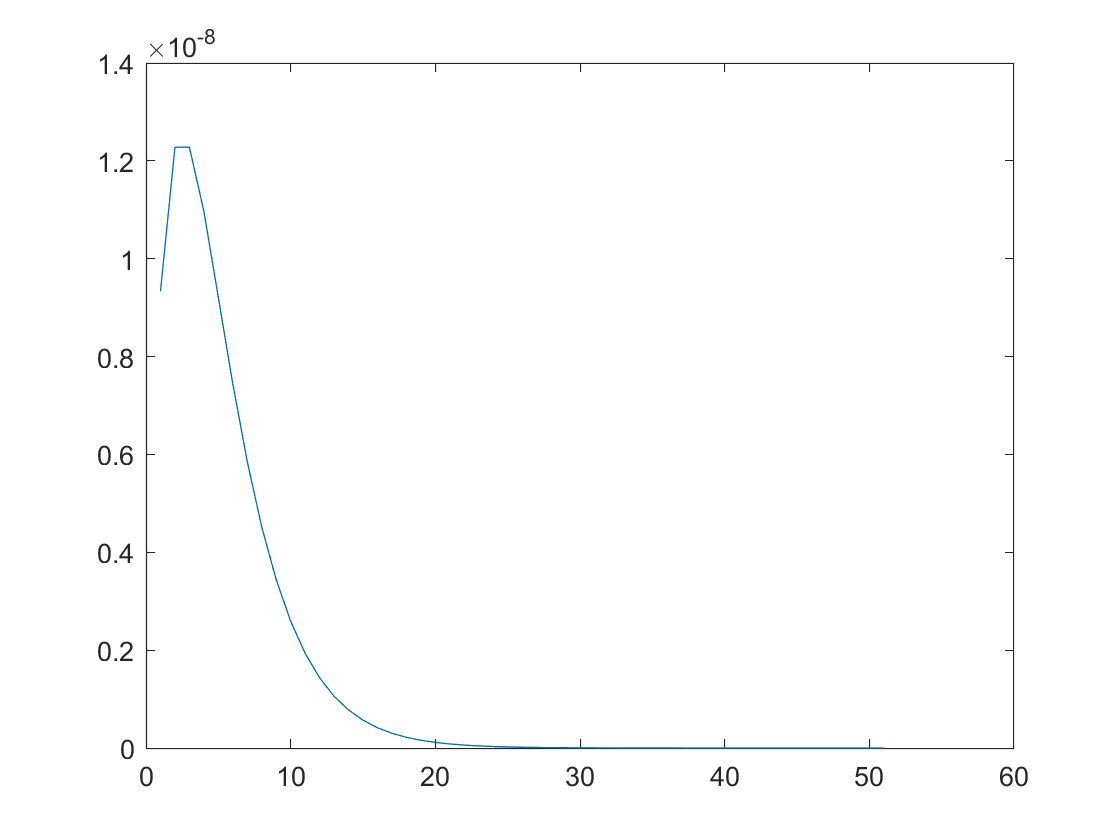

MSD_fit_lsq = PDE_MSD_func(p, t)